# Disambiguating the shoreline

This guide explains how to more clearly delineate the shoreline in a bathymetry representation

## About

In some cases, particularly where fast flow speeds occur, issues can arise in NewDepomod associated with the interception of particles and the seabed around the shoreline. This may cause simulations to fail. One approach that helps to minimse this issue is to disambiguate the shoreline - that is, make the shoreline more abrupt. This is done by setting all bathymetry values between +10 (land) and a specified lower threshold (default, -2 m) to the specified lower threshold.

## Initialise original bathymetry data

We start with an original bathymetry representation

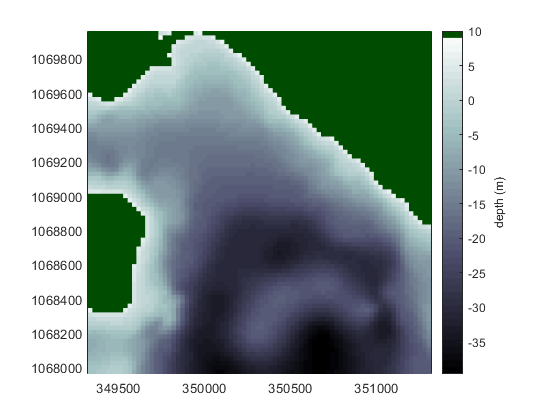

projectDir = 'C:\newdepomod_projects\bay_of_fish';
project    = Depomod.Project.create(projectDir);
bathy      = project.bathymetry;

bathy.plot

## Disambiguate the shoreline

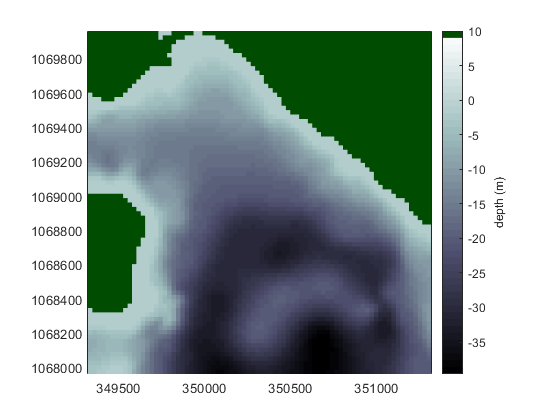

bathy.disambiguateShoreline

bathy.plot

Noteice that the shoreline now has no positive values (shown previously in or close to white).

## Saving new data

Any changes to the bathymetry such as these must be written to file if they are to take effect in the software.

bathy.toFile